% Import data from 'Filip.txt'.
A = importdata('Filip.txt');

% Extract the x and y values from imported data.
x = A(:, 2);
y = A(:, 1);

% Perform polynomial regression of degree 10.
p = polyfit(x, y, 10);

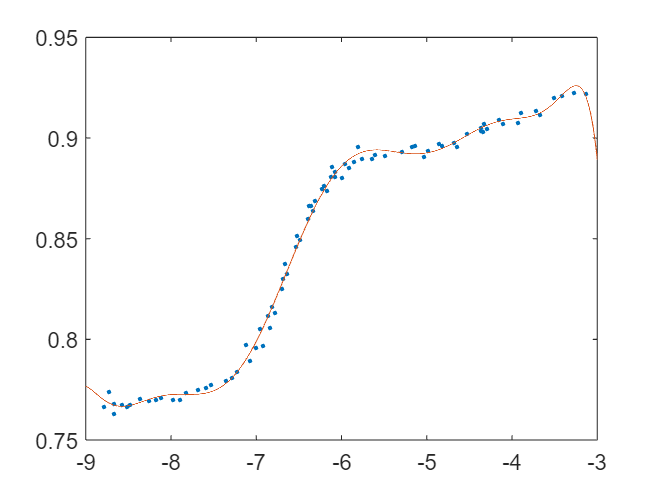


% Generate a range of x values for plotting.
x1 = linspace(-9, -3, 5000);

% Calculate the corresponding y values using the polynomial fit.
y1 = polyval(p, x1);

% Plot the original data points as dots and the polynomial fit curve.
plot(x, y, '.');
hold on
plot(x1, y1);
hold off


% Calculate and print the residual obtained.
residual = norm(y - polyval(p, x));
fprintf('Residual obtained = %.9f\n', residual);

Residual obtained = 0.028210838



% Initialize a matrix A for building the polynomial design matrix.
A = zeros(82, 11);

% Populate the design matrix A with powers of x values.
for i = 1:82
    t = x(i);
    for j = 0:10
        A(i, j + 1) = t^j;
    end
end

k = 1.0;  % Scaling factor
n = length(y);  % Number of data points
p = 10;  % Degree of the polynomial fit

% Calculate the RSD
RSD = sqrt((k * residual^2) / (n - p));
fprintf('NIST Residual Standard Deviation (RSD) = %.9f\n', RSD);

NIST Residual Standard Deviation (RSD) = 0.003324679



% Compute the polynomial fit using the backslash command
coeff_backslash = A \ y;

residual_backslash = norm(y - polyval(coeff_backslash, x));


% Compute the polynomial fit using the pseudoinverse
coeff_pinv = pinv(A) * y;
residual_pinv = norm(y - polyval(coeff_pinv, x));

% Compute the polynomial fit using the normal equations
coeff_normal = (A' * A) \ (A' * y);

residual_normal = norm(y - polyval(coeff_normal, x));

% Create a table to display coefficients and residuals
coefficients = [coeff_backslash, coeff_pinv, coeff_normal];
residuals = [residual_backslash, residual_pinv, residual_normal];

method_names = {'Backslash', 'Pseudoinverse', 'Normal Equations'};
T = table(method_names', coefficients', residuals', ...
    'VariableNames', {'Method', 'Coefficients', 'Residual'});

disp(T);

           Method           Coefficients     Residual 
    ____________________    ____________    __________

    {'Backslash'       }    1×11 double     5.7464e+10
    {'Pseudoinverse'   }    1×11 double     5.8687e+10
    {'Normal Equations'}    1×11 double     1.9708e+11



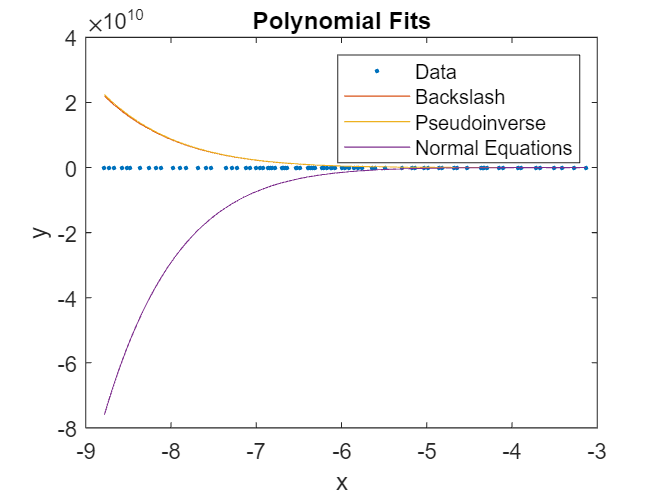


% Plot the data points
plot(x, y, '.');

hold on

% Plot the polynomial fits for each method
x_range = linspace(min(x), max(x), 500);  % Generate x values for plotting curves
y_backslash = polyval(coeff_backslash, x_range);
y_pinv = polyval(coeff_pinv, x_range);
y_normal = polyval(coeff_normal, x_range);

plot(x_range, y_backslash);
plot(x_range, y_pinv);
plot(x_range, y_normal);

hold off

% Add legend and labels to the plot
legend('Data', 'Backslash', 'Pseudoinverse', 'Normal Equations');
xlabel('x');
ylabel('y');
title('Polynomial Fits');